clearvars;
clear all

% Global constants
global kb q0 me T0 ne_0 CO2 O T_Ke T_Ki T_Je T_Ji T_Ee T_Ei XO2p XCO2p XOp O2p_0 CO2p_0 Op_0 v1 k2 v3 k4 k5 k6 k7 k8 k9 k10
kb = 1.3806e-23;
q0 = 1.602e-19;
me = 9.109e-31;
T0 = 2.5e-4;

fName1 = 'input/tempProfiles.in';
fid = fopen(fName1,'r');
if fid == -1
    disp("File "+fName1+" doesn't currently exist in "+pwd);
    return;
end
linenum1 = 2;
for i=1:301
    line1(i,:) = textscan(fid,'%f %f %f %f %f %f',1, 'headerlines',1);
end
line1 = cell2mat(line1);

fName2 = 'input/Partition.in';
fid = fopen(fName2,'r');
if fid == -1
    disp("File "+fName2+" doesn't currently exist in "+pwd);
    return;
end
linenum2 = 2;
for i=1:301
    line2(i,:) = textscan(fid,'%f %f %f %f',1, 'headerlines',1);
end
line2 = cell2mat(line2);
fclose(fid);


for i=1:height(line1)
    i
    alt  = line1(i,1);
    O    = line1(i,2);
    CO2  = line1(i,3);
    ne_0 = line1(i,4);
    T_Ke = line1(i,5);
    T_Ki = line1(i,6);
    
    XO2p  = line2(i,2);
    XCO2p = line2(i,3);
    XOp   = line2(i,4);
    
    T_Je = T_Ke*kb;
    T_Ji = T_Ki*kb;
    
    T_Ee = T_Je/q0;
    T_Ei = T_Ji/q0;
    
    O2p_0 = XO2p*ne_0;
    CO2p_0 = XCO2p*ne_0;
    Op_0 = XOp*ne_0;
    ne_0 = O2p_0 + CO2p_0 + Op_0;
    
    
    % Reaction constants
    v1 = 5e-7; % 1/s
    k2 = 0;                            %  Itikawa2002 has no Xsec for E < 1eV
    v3 = 2e-7; % 1/s
    k4 = 9e-9*T_Ee^0.7*exp(-13.6/T_Ee); %  This is way too low
    
    if (T_Ke<1200)
        k5 = 1.95e-7*(300/T_Ke)^0.7;
    else
        k5 = 7.38e-8*(1200/T_Ke)^0.56;
    end
    
    k6 = 3.1e-7*sqrt(300/T_Ke);
    k7 = 3.7e-12*(250/T_Ke)^0.7;
    k8 = 1.64e-10;
    k9 = 9.6e-11;
    
    if (T_Ke>800)
        k10 = 1.1e-9;
    else
        k10 = 1.1e-9*(800/T_Ki)^0.39;  % cm^-3/s
    end
   
    x0 = [CO2p_0, O2p_0, Op_0, ne_0];
    [sol,~,exitflag] = fsolve(@SOE,x0);
    if (exitflag >= 0)
        fprintf('CO2+ = %.2e\nO2+  = %.2e\nO+   = %.2e\nne   = %.2e\n\n', sol(1),sol(2),sol(3),sol(4));
        data(i,:) = sol(:);
    else
        data(i,:) = [-1 -1 -1 -1];
    end
end

i = 1


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 6.66e-01
O2+  = 2.45e+06
O+   = 5.25e+05
ne   = 2.98e+06



i = 2


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 6.82e-01
O2+  = 2.49e+06
O+   = 5.12e+05
ne   = 3.00e+06



i = 3


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 7.00e-01
O2+  = 2.52e+06
O+   = 4.99e+05
ne   = 3.02e+06



i = 4


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 7.17e-01
O2+  = 2.55e+06
O+   = 4.87e+05
ne   = 3.04e+06



i = 5


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 7.55e-01
O2+  = 2.60e+06
O+   = 4.63e+05
ne   = 3.07e+06



i = 6


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 8.13e-01
O2+  = 2.65e+06
O+   = 4.30e+05
ne   = 3.08e+06



i = 7


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 8.71e-01
O2+  = 2.69e+06
O+   = 4.01e+05
ne   = 3.09e+06



i = 8


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 9.25e-01
O2+  = 2.74e+06
O+   = 3.78e+05
ne   = 3.11e+06



i = 9


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 9.80e-01
O2+  = 2.78e+06
O+   = 3.57e+05
ne   = 3.14e+06



i = 10


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.04e+00
O2+  = 2.82e+06
O+   = 3.36e+05
ne   = 3.15e+06



i = 11


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.10e+00
O2+  = 2.86e+06
O+   = 3.19e+05
ne   = 3.18e+06



i = 12


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.15e+00
O2+  = 2.90e+06
O+   = 3.03e+05
ne   = 3.21e+06



i = 13


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.21e+00
O2+  = 2.95e+06
O+   = 2.88e+05
ne   = 3.23e+06



i = 14


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.27e+00
O2+  = 2.99e+06
O+   = 2.75e+05
ne   = 3.26e+06



i = 15


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.33e+00
O2+  = 3.03e+06
O+   = 2.64e+05
ne   = 3.29e+06



i = 16


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.38e+00
O2+  = 3.07e+06
O+   = 2.54e+05
ne   = 3.32e+06



i = 17


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.43e+00
O2+  = 3.11e+06
O+   = 2.44e+05
ne   = 3.36e+06



i = 18


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.50e+00
O2+  = 3.15e+06
O+   = 2.33e+05
ne   = 3.38e+06



i = 19


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.55e+00
O2+  = 3.19e+06
O+   = 2.26e+05
ne   = 3.42e+06



i = 20


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.61e+00
O2+  = 3.23e+06
O+   = 2.17e+05
ne   = 3.45e+06



i = 21


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.66e+00
O2+  = 3.27e+06
O+   = 2.10e+05
ne   = 3.48e+06



i = 22


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.72e+00
O2+  = 3.32e+06
O+   = 2.03e+05
ne   = 3.52e+06



i = 23


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.78e+00
O2+  = 3.36e+06
O+   = 1.97e+05
ne   = 3.55e+06



i = 24


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.84e+00
O2+  = 3.40e+06
O+   = 1.90e+05
ne   = 3.59e+06



i = 25


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.90e+00
O2+  = 3.44e+06
O+   = 1.84e+05
ne   = 3.62e+06



i = 26


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.95e+00
O2+  = 3.48e+06
O+   = 1.79e+05
ne   = 3.66e+06



i = 27


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.02e+00
O2+  = 3.52e+06
O+   = 1.73e+05
ne   = 3.69e+06



i = 28


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.07e+00
O2+  = 3.57e+06
O+   = 1.69e+05
ne   = 3.74e+06



i = 29


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.13e+00
O2+  = 3.61e+06
O+   = 1.64e+05
ne   = 3.77e+06



i = 30


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.19e+00
O2+  = 3.65e+06
O+   = 1.60e+05
ne   = 3.81e+06



i = 31


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.25e+00
O2+  = 3.70e+06
O+   = 1.56e+05
ne   = 3.85e+06



i = 32


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.30e+00
O2+  = 3.74e+06
O+   = 1.52e+05
ne   = 3.89e+06



i = 33


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.36e+00
O2+  = 3.78e+06
O+   = 1.48e+05
ne   = 3.93e+06



i = 34


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.42e+00
O2+  = 3.83e+06
O+   = 1.45e+05
ne   = 3.97e+06



i = 35


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.48e+00
O2+  = 3.87e+06
O+   = 1.41e+05
ne   = 4.01e+06



i = 36


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.56e+00
O2+  = 3.92e+06
O+   = 1.37e+05
ne   = 4.06e+06



i = 37


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.73e+00
O2+  = 3.97e+06
O+   = 1.28e+05
ne   = 4.10e+06



i = 38


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.90e+00
O2+  = 4.02e+06
O+   = 1.21e+05
ne   = 4.14e+06



i = 39


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 3.06e+00
O2+  = 4.08e+06
O+   = 1.14e+05
ne   = 4.19e+06



i = 40


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 3.24e+00
O2+  = 4.12e+06
O+   = 1.08e+05
ne   = 4.23e+06



i = 41


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 3.40e+00
O2+  = 4.18e+06
O+   = 1.03e+05
ne   = 4.28e+06



i = 42


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 3.58e+00
O2+  = 4.23e+06
O+   = 9.79e+04
ne   = 4.33e+06



i = 43


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 3.75e+00
O2+  = 4.28e+06
O+   = 9.35e+04
ne   = 4.38e+06



i = 44


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 3.92e+00
O2+  = 4.33e+06
O+   = 8.93e+04
ne   = 4.42e+06



i = 45


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 4.08e+00
O2+  = 4.39e+06
O+   = 8.57e+04
ne   = 4.48e+06



i = 46


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 4.26e+00
O2+  = 4.44e+06
O+   = 8.22e+04
ne   = 4.52e+06



i = 47


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 4.43e+00
O2+  = 4.50e+06
O+   = 7.91e+04
ne   = 4.57e+06



i = 48


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 4.60e+00
O2+  = 4.55e+06
O+   = 7.61e+04
ne   = 4.63e+06



i = 49


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 4.77e+00
O2+  = 4.60e+06
O+   = 7.34e+04
ne   = 4.68e+06



i = 50


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 4.95e+00
O2+  = 4.66e+06
O+   = 7.08e+04
ne   = 4.73e+06



i = 51


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 5.10e+00
O2+  = 4.72e+06
O+   = 6.87e+04
ne   = 4.78e+06



i = 52


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 5.30e+00
O2+  = 4.77e+06
O+   = 6.62e+04
ne   = 4.84e+06



i = 53


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 5.48e+00
O2+  = 4.83e+06
O+   = 6.39e+04
ne   = 4.89e+06



i = 54


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 5.66e+00
O2+  = 4.89e+06
O+   = 6.20e+04
ne   = 4.95e+06



i = 55


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 5.81e+00
O2+  = 4.95e+06
O+   = 6.03e+04
ne   = 5.01e+06



i = 56


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 6.02e+00
O2+  = 5.00e+06
O+   = 5.83e+04
ne   = 5.06e+06



i = 57


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 6.20e+00
O2+  = 5.06e+06
O+   = 5.66e+04
ne   = 5.12e+06



i = 58


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 6.37e+00
O2+  = 5.12e+06
O+   = 5.50e+04
ne   = 5.17e+06



i = 59


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 6.52e+00
O2+  = 5.18e+06
O+   = 5.38e+04
ne   = 5.24e+06



i = 60


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 6.72e+00
O2+  = 5.24e+06
O+   = 5.22e+04
ne   = 5.29e+06



i = 61


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 6.89e+00
O2+  = 5.30e+06
O+   = 5.09e+04
ne   = 5.35e+06



i = 62


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 7.05e+00
O2+  = 5.37e+06
O+   = 4.98e+04
ne   = 5.42e+06



i = 63


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 7.24e+00
O2+  = 5.43e+06
O+   = 4.84e+04
ne   = 5.48e+06



i = 64


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 7.41e+00
O2+  = 5.49e+06
O+   = 4.73e+04
ne   = 5.54e+06



i = 65


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 7.61e+00
O2+  = 5.56e+06
O+   = 4.61e+04
ne   = 5.60e+06



i = 66


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 7.77e+00
O2+  = 5.62e+06
O+   = 4.52e+04
ne   = 5.66e+06



i = 67


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 8.21e+00
O2+  = 5.69e+06
O+   = 4.28e+04
ne   = 5.73e+06



i = 68


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 8.66e+00
O2+  = 5.76e+06
O+   = 4.05e+04
ne   = 5.80e+06



i = 69


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 9.10e+00
O2+  = 5.84e+06
O+   = 3.86e+04
ne   = 5.88e+06



i = 70


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 9.55e+00
O2+  = 5.91e+06
O+   = 3.68e+04
ne   = 5.95e+06



i = 71


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 9.98e+00
O2+  = 5.99e+06
O+   = 3.52e+04
ne   = 6.02e+06



i = 72


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.04e+01
O2+  = 6.07e+06
O+   = 3.37e+04
ne   = 6.10e+06



i = 73


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.09e+01
O2+  = 6.14e+06
O+   = 3.23e+04
ne   = 6.17e+06



i = 74


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.13e+01
O2+  = 6.22e+06
O+   = 3.10e+04
ne   = 6.25e+06



i = 75


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.18e+01
O2+  = 6.30e+06
O+   = 2.98e+04
ne   = 6.33e+06



i = 76


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.23e+01
O2+  = 6.38e+06
O+   = 2.87e+04
ne   = 6.41e+06



i = 77


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.27e+01
O2+  = 6.46e+06
O+   = 2.77e+04
ne   = 6.49e+06



i = 78


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.32e+01
O2+  = 6.54e+06
O+   = 2.67e+04
ne   = 6.57e+06



i = 79


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.36e+01
O2+  = 6.62e+06
O+   = 2.58e+04
ne   = 6.65e+06



i = 80


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.41e+01
O2+  = 6.70e+06
O+   = 2.50e+04
ne   = 6.73e+06



i = 81


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.46e+01
O2+  = 6.78e+06
O+   = 2.41e+04
ne   = 6.81e+06



i = 82


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.50e+01
O2+  = 6.87e+06
O+   = 2.34e+04
ne   = 6.89e+06



i = 83


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.55e+01
O2+  = 6.95e+06
O+   = 2.27e+04
ne   = 6.98e+06



i = 84


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.60e+01
O2+  = 7.04e+06
O+   = 2.20e+04
ne   = 7.06e+06



i = 85


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.65e+01
O2+  = 7.13e+06
O+   = 2.14e+04
ne   = 7.15e+06



i = 86


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.69e+01
O2+  = 7.21e+06
O+   = 2.08e+04
ne   = 7.23e+06



i = 87


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.74e+01
O2+  = 7.30e+06
O+   = 2.02e+04
ne   = 7.32e+06



i = 88


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.80e+01
O2+  = 7.38e+06
O+   = 1.96e+04
ne   = 7.40e+06



i = 89


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.83e+01
O2+  = 7.49e+06
O+   = 1.92e+04
ne   = 7.50e+06



i = 90


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.89e+01
O2+  = 7.56e+06
O+   = 1.87e+04
ne   = 7.58e+06



i = 91


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.94e+01
O2+  = 7.67e+06
O+   = 1.82e+04
ne   = 7.68e+06



i = 92


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.99e+01
O2+  = 7.74e+06
O+   = 1.77e+04
ne   = 7.76e+06



i = 93


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.04e+01
O2+  = 7.84e+06
O+   = 1.73e+04
ne   = 7.86e+06



i = 94


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.07e+01
O2+  = 7.95e+06
O+   = 1.71e+04
ne   = 7.96e+06



i = 95


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.13e+01
O2+  = 8.05e+06
O+   = 1.66e+04
ne   = 8.06e+06



i = 96


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 2.24e+01
O2+  = 8.15e+06
O+   = 1.58e+04
ne   = 8.17e+06



i = 97


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.35e+01
O2+  = 8.26e+06
O+   = 1.50e+04
ne   = 8.27e+06



i = 98


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.44e+01
O2+  = 8.39e+06
O+   = 1.45e+04
ne   = 8.40e+06



i = 99


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.56e+01
O2+  = 8.49e+06
O+   = 1.38e+04
ne   = 8.50e+06



i = 100


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.67e+01
O2+  = 8.62e+06
O+   = 1.33e+04
ne   = 8.63e+06



i = 101


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.79e+01
O2+  = 8.72e+06
O+   = 1.27e+04
ne   = 8.73e+06



i = 102


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.88e+01
O2+  = 8.84e+06
O+   = 1.23e+04
ne   = 8.86e+06



i = 103


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 2.99e+01
O2+  = 8.97e+06
O+   = 1.19e+04
ne   = 8.98e+06



i = 104


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 3.10e+01
O2+  = 9.09e+06
O+   = 1.14e+04
ne   = 9.10e+06



i = 105


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 3.20e+01
O2+  = 9.22e+06
O+   = 1.11e+04
ne   = 9.23e+06



i = 106


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 3.33e+01
O2+  = 9.34e+06
O+   = 1.07e+04
ne   = 9.35e+06



i = 107


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 3.44e+01
O2+  = 9.46e+06
O+   = 1.03e+04
ne   = 9.47e+06



i = 108


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 3.56e+01
O2+  = 9.57e+06
O+   = 9.99e+03
ne   = 9.58e+06



i = 109


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 3.68e+01
O2+  = 9.69e+06
O+   = 9.67e+03
ne   = 9.70e+06



i = 110


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 3.78e+01
O2+  = 9.83e+06
O+   = 9.42e+03
ne   = 9.84e+06



i = 111


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 3.91e+01
O2+  = 9.95e+06
O+   = 9.11e+03
ne   = 9.96e+06



i = 112


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 4.02e+01
O2+  = 1.01e+07
O+   = 8.86e+03
ne   = 1.01e+07



i = 113


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 4.13e+01
O2+  = 1.02e+07
O+   = 8.64e+03
ne   = 1.02e+07



i = 114


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 4.25e+01
O2+  = 1.04e+07
O+   = 8.40e+03
ne   = 1.04e+07



i = 115


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 4.36e+01
O2+  = 1.05e+07
O+   = 8.18e+03
ne   = 1.05e+07



i = 116


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 4.48e+01
O2+  = 1.06e+07
O+   = 7.97e+03
ne   = 1.06e+07



i = 117


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 4.61e+01
O2+  = 1.08e+07
O+   = 7.75e+03
ne   = 1.08e+07



i = 118


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 4.74e+01
O2+  = 1.09e+07
O+   = 7.55e+03
ne   = 1.09e+07



i = 119


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 4.84e+01
O2+  = 1.10e+07
O+   = 7.39e+03
ne   = 1.10e+07



i = 120


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 4.98e+01
O2+  = 1.12e+07
O+   = 7.19e+03
ne   = 1.12e+07



i = 121


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 5.09e+01
O2+  = 1.13e+07
O+   = 7.03e+03
ne   = 1.13e+07



i = 122


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 5.25e+01
O2+  = 1.15e+07
O+   = 6.83e+03
ne   = 1.15e+07



i = 123


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 5.48e+01
O2+  = 1.16e+07
O+   = 6.55e+03
ne   = 1.16e+07



i = 124


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 5.72e+01
O2+  = 1.18e+07
O+   = 6.28e+03
ne   = 1.18e+07



i = 125


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 5.95e+01
O2+  = 1.20e+07
O+   = 6.05e+03
ne   = 1.20e+07



i = 126


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 6.19e+01
O2+  = 1.22e+07
O+   = 5.81e+03
ne   = 1.22e+07



i = 127


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 6.43e+01
O2+  = 1.23e+07
O+   = 5.60e+03
ne   = 1.24e+07



i = 128


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 6.68e+01
O2+  = 1.25e+07
O+   = 5.40e+03
ne   = 1.25e+07



i = 129


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 6.91e+01
O2+  = 1.27e+07
O+   = 5.22e+03
ne   = 1.27e+07



i = 130


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 7.15e+01
O2+  = 1.29e+07
O+   = 5.05e+03
ne   = 1.29e+07



i = 131


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 7.40e+01
O2+  = 1.31e+07
O+   = 4.89e+03
ne   = 1.31e+07



i = 132


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 7.68e+01
O2+  = 1.33e+07
O+   = 4.72e+03
ne   = 1.33e+07



i = 133


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 7.94e+01
O2+  = 1.35e+07
O+   = 4.57e+03
ne   = 1.35e+07



i = 134


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 8.18e+01
O2+  = 1.37e+07
O+   = 4.44e+03
ne   = 1.37e+07



i = 135


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 8.47e+01
O2+  = 1.39e+07
O+   = 4.29e+03
ne   = 1.39e+07



i = 136


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 8.75e+01
O2+  = 1.40e+07
O+   = 4.17e+03
ne   = 1.40e+07



i = 137


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 8.98e+01
O2+  = 1.42e+07
O+   = 4.06e+03
ne   = 1.42e+07



i = 138


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 9.25e+01
O2+  = 1.44e+07
O+   = 3.95e+03
ne   = 1.44e+07



i = 139


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 9.51e+01
O2+  = 1.46e+07
O+   = 3.84e+03
ne   = 1.46e+07



i = 140


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 9.81e+01
O2+  = 1.48e+07
O+   = 3.73e+03
ne   = 1.48e+07



i = 141


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.01e+02
O2+  = 1.50e+07
O+   = 3.64e+03
ne   = 1.50e+07



i = 142


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.04e+02
O2+  = 1.52e+07
O+   = 3.54e+03
ne   = 1.52e+07



i = 143


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.07e+02
O2+  = 1.54e+07
O+   = 3.45e+03
ne   = 1.54e+07



i = 144


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.10e+02
O2+  = 1.56e+07
O+   = 3.36e+03
ne   = 1.56e+07



i = 145


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.12e+02
O2+  = 1.58e+07
O+   = 3.28e+03
ne   = 1.58e+07



i = 146


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.15e+02
O2+  = 1.60e+07
O+   = 3.20e+03
ne   = 1.60e+07



i = 147


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.20e+02
O2+  = 1.63e+07
O+   = 3.09e+03
ne   = 1.63e+07



i = 148


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.25e+02
O2+  = 1.65e+07
O+   = 2.97e+03
ne   = 1.65e+07



i = 149


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.30e+02
O2+  = 1.68e+07
O+   = 2.87e+03
ne   = 1.68e+07



i = 150


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.34e+02
O2+  = 1.71e+07
O+   = 2.77e+03
ne   = 1.71e+07



i = 151


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.39e+02
O2+  = 1.74e+07
O+   = 2.67e+03
ne   = 1.74e+07



i = 152


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.45e+02
O2+  = 1.77e+07
O+   = 2.58e+03
ne   = 1.77e+07



i = 153


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.50e+02
O2+  = 1.79e+07
O+   = 2.50e+03
ne   = 1.79e+07



i = 154


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.55e+02
O2+  = 1.82e+07
O+   = 2.42e+03
ne   = 1.82e+07



i = 155


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.61e+02
O2+  = 1.85e+07
O+   = 2.34e+03
ne   = 1.85e+07



i = 156


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.66e+02
O2+  = 1.88e+07
O+   = 2.27e+03
ne   = 1.88e+07



i = 157


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.72e+02
O2+  = 1.91e+07
O+   = 2.20e+03
ne   = 1.91e+07



i = 158


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.78e+02
O2+  = 1.93e+07
O+   = 2.13e+03
ne   = 1.93e+07



i = 159


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.84e+02
O2+  = 1.96e+07
O+   = 2.07e+03
ne   = 1.96e+07



i = 160


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.90e+02
O2+  = 1.99e+07
O+   = 2.01e+03
ne   = 1.99e+07



i = 161


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.96e+02
O2+  = 2.02e+07
O+   = 1.95e+03
ne   = 2.02e+07



i = 162


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.02e+02
O2+  = 2.05e+07
O+   = 1.90e+03
ne   = 2.05e+07



i = 163


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 2.08e+02
O2+  = 2.07e+07
O+   = 1.85e+03
ne   = 2.08e+07



i = 164


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 2.14e+02
O2+  = 2.10e+07
O+   = 1.80e+03
ne   = 2.10e+07



i = 165


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.21e+02
O2+  = 2.13e+07
O+   = 1.75e+03
ne   = 2.13e+07



i = 166


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.28e+02
O2+  = 2.16e+07
O+   = 1.70e+03
ne   = 2.16e+07



i = 167


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.35e+02
O2+  = 2.19e+07
O+   = 1.65e+03
ne   = 2.19e+07



i = 168


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 2.40e+02
O2+  = 2.22e+07
O+   = 1.62e+03
ne   = 2.22e+07



i = 169


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.51e+02
O2+  = 2.26e+07
O+   = 1.56e+03
ne   = 2.26e+07



i = 170


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.61e+02
O2+  = 2.30e+07
O+   = 1.51e+03
ne   = 2.30e+07



i = 171


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 2.70e+02
O2+  = 2.34e+07
O+   = 1.46e+03
ne   = 2.34e+07



i = 172


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 2.81e+02
O2+  = 2.38e+07
O+   = 1.41e+03
ne   = 2.38e+07



i = 173


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 2.91e+02
O2+  = 2.42e+07
O+   = 1.37e+03
ne   = 2.42e+07



i = 174


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 3.00e+02
O2+  = 2.46e+07
O+   = 1.33e+03
ne   = 2.46e+07



i = 175


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 3.13e+02
O2+  = 2.50e+07
O+   = 1.29e+03
ne   = 2.50e+07



i = 176


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 3.25e+02
O2+  = 2.54e+07
O+   = 1.24e+03
ne   = 2.54e+07



i = 177


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 3.35e+02
O2+  = 2.58e+07
O+   = 1.21e+03
ne   = 2.58e+07



i = 178


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 3.46e+02
O2+  = 2.62e+07
O+   = 1.18e+03
ne   = 2.62e+07



i = 179


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 3.60e+02
O2+  = 2.66e+07
O+   = 1.14e+03
ne   = 2.66e+07



i = 180


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 3.71e+02
O2+  = 2.70e+07
O+   = 1.11e+03
ne   = 2.70e+07



i = 181


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 3.83e+02
O2+  = 2.74e+07
O+   = 1.08e+03
ne   = 2.74e+07



i = 182


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 3.96e+02
O2+  = 2.78e+07
O+   = 1.05e+03
ne   = 2.79e+07



i = 183


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 4.12e+02
O2+  = 2.82e+07
O+   = 1.02e+03
ne   = 2.82e+07



i = 184


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 4.26e+02
O2+  = 2.86e+07
O+   = 9.88e+02
ne   = 2.86e+07



i = 185


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 4.40e+02
O2+  = 2.90e+07
O+   = 9.63e+02
ne   = 2.90e+07



i = 186


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 4.55e+02
O2+  = 2.94e+07
O+   = 9.37e+02
ne   = 2.94e+07



i = 187


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 4.67e+02
O2+  = 2.99e+07
O+   = 9.16e+02
ne   = 2.99e+07



i = 188


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 4.86e+02
O2+  = 3.04e+07
O+   = 8.87e+02
ne   = 3.04e+07



i = 189


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 5.04e+02
O2+  = 3.10e+07
O+   = 8.61e+02
ne   = 3.10e+07



i = 190


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 5.24e+02
O2+  = 3.16e+07
O+   = 8.36e+02
ne   = 3.16e+07



i = 191


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 5.42e+02
O2+  = 3.22e+07
O+   = 8.12e+02
ne   = 3.22e+07



i = 192


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 5.63e+02
O2+  = 3.28e+07
O+   = 7.88e+02
ne   = 3.28e+07



i = 193


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 5.85e+02
O2+  = 3.33e+07
O+   = 7.66e+02
ne   = 3.33e+07



i = 194


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 6.07e+02
O2+  = 3.39e+07
O+   = 7.44e+02
ne   = 3.39e+07



i = 195


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 6.31e+02
O2+  = 3.45e+07
O+   = 7.22e+02
ne   = 3.45e+07



i = 196


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 6.55e+02
O2+  = 3.51e+07
O+   = 7.02e+02
ne   = 3.51e+07



i = 197


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 6.77e+02
O2+  = 3.57e+07
O+   = 6.84e+02
ne   = 3.57e+07



i = 198


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 7.04e+02
O2+  = 3.63e+07
O+   = 6.64e+02
ne   = 3.63e+07



i = 199


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 7.29e+02
O2+  = 3.69e+07
O+   = 6.47e+02
ne   = 3.69e+07



i = 200


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 7.58e+02
O2+  = 3.75e+07
O+   = 6.29e+02
ne   = 3.75e+07



i = 201


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 7.84e+02
O2+  = 3.81e+07
O+   = 6.14e+02
ne   = 3.81e+07



i = 202


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 8.11e+02
O2+  = 3.87e+07
O+   = 5.99e+02
ne   = 3.87e+07



i = 203


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 8.45e+02
O2+  = 3.93e+07
O+   = 5.82e+02
ne   = 3.93e+07



i = 204


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 8.73e+02
O2+  = 3.99e+07
O+   = 5.68e+02
ne   = 3.99e+07



i = 205


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 9.12e+02
O2+  = 4.08e+07
O+   = 5.51e+02
ne   = 4.08e+07



i = 206


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 9.41e+02
O2+  = 4.16e+07
O+   = 5.39e+02
ne   = 4.16e+07



i = 207


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 9.81e+02
O2+  = 4.25e+07
O+   = 5.24e+02
ne   = 4.25e+07



i = 208


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.02e+03
O2+  = 4.33e+07
O+   = 5.11e+02
ne   = 4.33e+07



i = 209


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.05e+03
O2+  = 4.41e+07
O+   = 5.00e+02
ne   = 4.41e+07



i = 210


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.10e+03
O2+  = 4.49e+07
O+   = 4.86e+02
ne   = 4.49e+07



i = 211


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.14e+03
O2+  = 4.57e+07
O+   = 4.74e+02
ne   = 4.57e+07



i = 212


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.18e+03
O2+  = 4.65e+07
O+   = 4.63e+02
ne   = 4.65e+07



i = 213


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.23e+03
O2+  = 4.73e+07
O+   = 4.52e+02
ne   = 4.73e+07



i = 214


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.28e+03
O2+  = 4.82e+07
O+   = 4.41e+02
ne   = 4.82e+07



i = 215


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.33e+03
O2+  = 4.90e+07
O+   = 4.30e+02
ne   = 4.90e+07



i = 216


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.38e+03
O2+  = 4.98e+07
O+   = 4.21e+02
ne   = 4.98e+07



i = 217


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.44e+03
O2+  = 5.07e+07
O+   = 4.11e+02
ne   = 5.07e+07



i = 218


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.50e+03
O2+  = 5.15e+07
O+   = 4.01e+02
ne   = 5.15e+07



i = 219


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.56e+03
O2+  = 5.25e+07
O+   = 3.92e+02
ne   = 5.25e+07



i = 220


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.62e+03
O2+  = 5.37e+07
O+   = 3.84e+02
ne   = 5.37e+07



i = 221


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.68e+03
O2+  = 5.49e+07
O+   = 3.76e+02
ne   = 5.49e+07



i = 222


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.75e+03
O2+  = 5.61e+07
O+   = 3.68e+02
ne   = 5.61e+07



i = 223


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.82e+03
O2+  = 5.74e+07
O+   = 2.37e+02
ne   = 5.74e+07



i = 224


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.89e+03
O2+  = 5.86e+07
O+   = 2.32e+02
ne   = 5.86e+07



i = 225


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.96e+03
O2+  = 5.99e+07
O+   = 2.26e+02
ne   = 5.99e+07



i = 226


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.04e+03
O2+  = 6.12e+07
O+   = 2.21e+02
ne   = 6.12e+07



i = 227


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 2.13e+03
O2+  = 6.25e+07
O+   = 2.16e+02
ne   = 6.25e+07



i = 228


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 2.22e+03
O2+  = 6.38e+07
O+   = 2.11e+02
ne   = 6.38e+07



i = 229


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 2.31e+03
O2+  = 6.52e+07
O+   = 2.07e+02
ne   = 6.52e+07



i = 230


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.41e+03
O2+  = 6.66e+07
O+   = 2.02e+02
ne   = 6.66e+07



i = 231


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.52e+03
O2+  = 6.80e+07
O+   = 1.98e+02
ne   = 6.80e+07



i = 232


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 2.63e+03
O2+  = 6.94e+07
O+   = 1.94e+02
ne   = 6.94e+07



i = 233


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 2.73e+03
O2+  = 7.12e+07
O+   = 1.91e+02
ne   = 7.12e+07



i = 234


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 2.83e+03
O2+  = 7.30e+07
O+   = 1.88e+02
ne   = 7.30e+07



i = 235


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 2.95e+03
O2+  = 7.50e+07
O+   = 1.85e+02
ne   = 7.50e+07



i = 236


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 3.08e+03
O2+  = 7.71e+07
O+   = 1.81e+02
ne   = 7.71e+07



i = 237


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 3.20e+03
O2+  = 7.90e+07
O+   = 1.78e+02
ne   = 7.90e+07



i = 238


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 3.32e+03
O2+  = 8.09e+07
O+   = 1.76e+02
ne   = 8.09e+07



i = 239


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 3.47e+03
O2+  = 8.31e+07
O+   = 1.73e+02
ne   = 8.31e+07



i = 240


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 3.62e+03
O2+  = 8.52e+07
O+   = 1.70e+02
ne   = 8.52e+07



i = 241


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 3.79e+03
O2+  = 8.74e+07
O+   = 1.67e+02
ne   = 8.74e+07



i = 242


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 3.94e+03
O2+  = 8.94e+07
O+   = 1.64e+02
ne   = 8.94e+07



i = 243


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 4.14e+03
O2+  = 9.18e+07
O+   = 1.61e+02
ne   = 9.18e+07



i = 244


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 4.33e+03
O2+  = 9.40e+07
O+   = 1.59e+02
ne   = 9.40e+07



i = 245


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 4.51e+03
O2+  = 9.69e+07
O+   = 1.57e+02
ne   = 9.69e+07



i = 246


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 4.68e+03
O2+  = 9.99e+07
O+   = 1.55e+02
ne   = 9.99e+07



i = 247


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 4.89e+03
O2+  = 1.03e+08
O+   = 1.52e+02
ne   = 1.03e+08



i = 248


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 5.05e+03
O2+  = 1.06e+08
O+   = 1.51e+02
ne   = 1.06e+08



i = 249


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 5.28e+03
O2+  = 1.09e+08
O+   = 1.49e+02
ne   = 1.09e+08



i = 250


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 5.52e+03
O2+  = 1.13e+08
O+   = 1.46e+02
ne   = 1.13e+08



i = 251


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 5.77e+03
O2+  = 1.16e+08
O+   = 1.44e+02
ne   = 1.16e+08



i = 252


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 6.04e+03
O2+  = 1.20e+08
O+   = 1.42e+02
ne   = 1.20e+08



i = 253


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 6.33e+03
O2+  = 1.23e+08
O+   = 1.41e+02
ne   = 1.23e+08



i = 254


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 6.63e+03
O2+  = 1.27e+08
O+   = 1.39e+02
ne   = 1.27e+08



i = 255


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 6.94e+03
O2+  = 1.30e+08
O+   = 1.37e+02
ne   = 1.31e+08



i = 256


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 7.28e+03
O2+  = 1.35e+08
O+   = 1.35e+02
ne   = 1.35e+08



i = 257


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 7.55e+03
O2+  = 1.40e+08
O+   = 1.34e+02
ne   = 1.40e+08



i = 258


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 7.91e+03
O2+  = 1.46e+08
O+   = 1.32e+02
ne   = 1.46e+08



i = 259


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 8.24e+03
O2+  = 1.51e+08
O+   = 1.30e+02
ne   = 1.51e+08



i = 260


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 8.64e+03
O2+  = 1.56e+08
O+   = 1.29e+02
ne   = 1.56e+08



i = 261


No solution found.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared, but the vector of function values
is not near zero as measured by the value of the function tolerance.

<stopping criteria details>


i = 262


No solution found.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared, but the vector of function values
is not near zero as measured by the value of the function tolerance.

<stopping criteria details>


i = 263


No solution found.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared, but the vector of function values
is not near zero as measured by the value of the function tolerance.

<stopping criteria details>


i = 264


No solution found.

fsolve stopped because the last step was ineffective. However, the vector of function
values is not near zero, as measured by the value of the function tolerance. 

<stopping criteria details>


i = 265


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 1.10e+04
O2+  = 1.86e+08
O+   = 1.21e+02
ne   = 1.86e+08



i = 266


No solution found.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared, but the vector of function values
is not near zero as measured by the value of the function tolerance.

<stopping criteria details>


i = 267


No solution found.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared, but the vector of function values
is not near zero as measured by the value of the function tolerance.

<stopping criteria details>


i = 268


No solution found.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared, but the vector of function values
is not near zero as measured by the value of the function tolerance.

<stopping criteria details>


i = 269


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.34e+04
O2+  = 2.23e+08
O+   = 1.15e+02
ne   = 2.23e+08



i = 270


No solution found.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared, but the vector of function values
is not near zero as measured by the value of the function tolerance.

<stopping criteria details>


i = 271


No solution found.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared, but the vector of function values
is not near zero as measured by the value of the function tolerance.

<stopping criteria details>


i = 272


No solution found.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared, but the vector of function values
is not near zero as measured by the value of the function tolerance.

<stopping criteria details>


i = 273


No solution found.

fsolve stopped because the last step was ineffective. However, the vector of function
values is not near zero, as measured by the value of the function tolerance. 

<stopping criteria details>


i = 274


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.80e+04
O2+  = 2.76e+08
O+   = 1.07e+02
ne   = 2.76e+08



i = 275


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.91e+04
O2+  = 2.94e+08
O+   = 1.06e+02
ne   = 2.94e+08



i = 276


No solution found.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared, but the vector of function values
is not near zero as measured by the value of the function tolerance.

<stopping criteria details>


i = 277


No solution found.

fsolve stopped because the last step was ineffective. However, the vector of function
values is not near zero, as measured by the value of the function tolerance. 

<stopping criteria details>


i = 278


No solution found.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared, but the vector of function values
is not near zero as measured by the value of the function tolerance.

<stopping criteria details>


i = 279


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


CO2+ = 2.50e+04
O2+  = 3.67e+08
O+   = 1.00e+02
ne   = 3.67e+08



i = 280


No solution found.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared, but the vector of function values
is not near zero as measured by the value of the function tolerance.

<stopping criteria details>


i = 281


No solution found.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared, but the vector of function values
is not near zero as measured by the value of the function tolerance.

<stopping criteria details>


i = 282


No solution found.

fsolve stopped because the last step was ineffective. However, the vector of function
values is not near zero, as measured by the value of the function tolerance. 

<stopping criteria details>


i = 283


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 3.45e+04
O2+  = 4.70e+08
O+   = 9.49e+01
ne   = 4.70e+08



i = 284


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 3.78e+04
O2+  = 5.03e+08
O+   = 9.37e+01
ne   = 5.03e+08



i = 285


No solution found.

fsolve stopped because the last step was ineffective. However, the vector of function
values is not near zero, as measured by the value of the function tolerance. 

<stopping criteria details>


i = 286


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 4.61e+04
O2+  = 5.70e+08
O+   = 9.14e+01
ne   = 5.70e+08



i = 287


No solution found.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared, but the vector of function values
is not near zero as measured by the value of the function tolerance.

<stopping criteria details>


i = 288


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 6.14e+04
O2+  = 6.53e+08
O+   = 8.92e+01
ne   = 6.53e+08



i = 289


No solution found.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared, but the vector of function values
is not near zero as measured by the value of the function tolerance.

<stopping criteria details>


i = 290


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 9.27e+04
O2+  = 7.50e+08
O+   = 8.70e+01
ne   = 7.50e+08



i = 291


No solution found.

fsolve stopped because the last step was ineffective. However, the vector of function
values is not near zero, as measured by the value of the function tolerance. 

<stopping criteria details>


i = 292


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.63e+05
O2+  = 8.59e+08
O+   = 8.52e+01
ne   = 8.60e+08



i = 293


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.91e+05
O2+  = 9.20e+08
O+   = 8.46e+01
ne   = 9.20e+08



i = 294


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 2.31e+05
O2+  = 9.86e+08
O+   = 8.40e+01
ne   = 9.87e+08



i = 295


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 2.93e+05
O2+  = 1.06e+09
O+   = 8.35e+01
ne   = 1.06e+09



i = 296


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 3.99e+05
O2+  = 1.13e+09
O+   = 8.30e+01
ne   = 1.13e+09



i = 297


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 5.11e+05
O2+  = 1.22e+09
O+   = 8.26e+01
ne   = 1.22e+09



i = 298


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 6.03e+05
O2+  = 1.31e+09
O+   = 8.22e+01
ne   = 1.31e+09



i = 299


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 7.32e+05
O2+  = 1.40e+09
O+   = 8.19e+01
ne   = 1.40e+09



i = 300


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 9.38e+05
O2+  = 1.51e+09
O+   = 8.17e+01
ne   = 1.51e+09



i = 301


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


CO2+ = 1.29e+06
O2+  = 1.62e+09
O+   = 8.15e+01
ne   = 1.62e+09



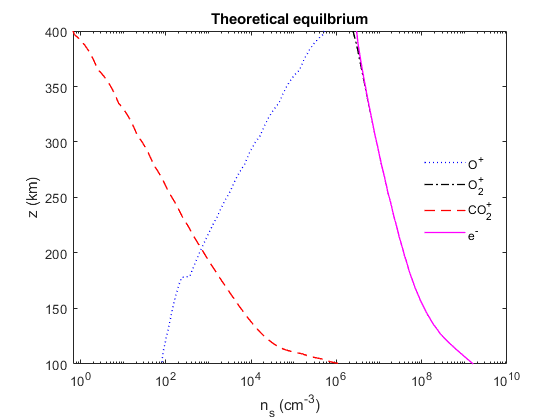

i = 1;
Z = line1(:,1)./1000;
tempdata = data;

while i <= height(tempdata)
    if (tempdata(i,1:4) < 0)
        tempdata(i,:) = [];
        Z(i) = [];
    else
        i = i+1;
    end
end

semilogx(tempdata(:,3),Z,'LineWidth',1,'Color','b','LineStyle',':');
hold on;
semilogx(tempdata(:,2),Z,'LineWidth',1,'Color','k','LineStyle','-.');
semilogx(tempdata(:,1),Z,'LineWidth',1,'Color','r','LineStyle','--');
semilogx(tempdata(:,4),Z,'LineWidth',1,'Color','m','LineStyle','-');
hold off;

legend('O^+','O_2^+','CO_2^+','e^-','Location','east');
legend boxoff;
title('Theoretical equilbrium');
xlabel("n_s (cm^-^3)");
ylabel("z (km)");
xlim([0,10^10]);
ylim([100 400]);

function F = SOE(x)
    global v1 k2 v3 k4 k5 k6 k7 k8 k9 k10 CO2 O

    CO2p = x(1);
    O2p  = x(2);
    Op   = x(3);
    ne   = x(4);
    
    R1  = v1*CO2;
    R2  = k2*CO2*ne;
    R3  = v3*O;
    R4  = k4*O*ne;
    R5  = k5*O2p*ne;
    R6  = k6*CO2p*ne;
    R7  = k7*Op*ne;
    R8  = k8*CO2p*O;
    R9  = k9*CO2p*O;
    R10 = k10*Op*CO2;
    
    CO2p_S = R1 + R2;
    CO2p_L = R6 + R8 + R9;
    
    O2p_S  = R8 + R10;
    O2p_L  = R5;

    Op_S   = R3 + R4 + R9;
    Op_L   = R7 + R10;
    
    F = [CO2p_S - CO2p_L,...
         O2p_S  - O2p_L,...
         Op_S   - Op_L,...
         ne - (CO2p + O2p + Op)];
end